clear ;
close all;
clc;

## Input from user

[dm]=input('Enter the message to be transmitted in unipolar NRZ form = ');
b=2*dm-1;                           % Biplor NRZ form
l=length(b);

## Prior Knowledge

T=50;                               % Bit duration
Eb=T/4;                             % Energy per bit
Fc=T/8;                             % Carrier frequency

## BPSK Logic

t=linspace(0,l,1000*l);
N=length(t);
Nsb=N/l;                            % Number of samples per bit
bb=repmat(b,Nsb,1);
bw=bb(:)';
w=sqrt(2*Eb/T)*cos(2*pi*Fc*t);      % BPSK representation
bpsk_w=bw.*w;

## Plots

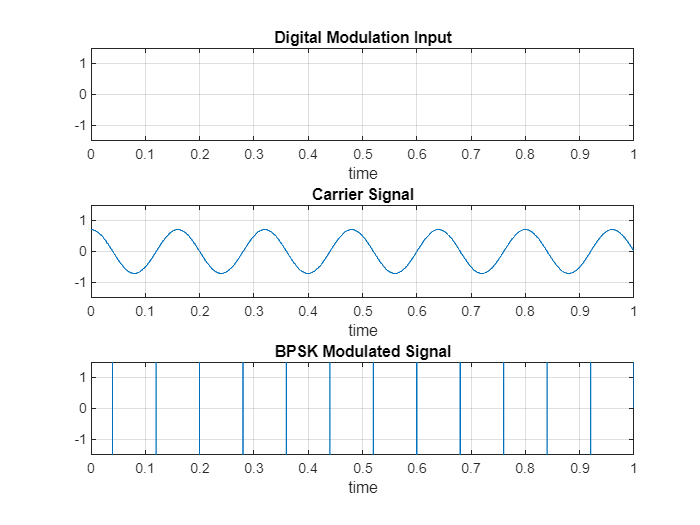

subplot(3,1,1);
plot(t,bw);
axis([0 l -1.5 1.5]);
xlabel('time');
title('Digital Modulation Input');
grid on;

subplot(3,1,2);
plot(t,w);
axis([0 l -1.5 1.5]);
xlabel('time');
title('Carrier Signal');
grid on;

subplot(3,1,3);
plot(t,bpsk_w);
axis([0 l -1.5 1.5]);
xlabel('time');
title('BPSK Modulated Signal');
grid on;